clear 
close all
clc
% To load the data
%addpath('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab')
%savepath
%dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240408\Results\Basler_acA2040-90uc__21599070__20240408_111238612_0001_diff_new.dat')
dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240611_new_A3\20240611_nonrot_2.4Hz_8mm_new_A3_separate_frames\Batch processing\Results\20240611_nonrot_2.4Hz_8mm_new_A3_frame_0010A_vel_new.dat');


% Copy dr to dr_new & delete rows and columns with only zeros

dr_new=dr;
%vx=dr.vx;
% Delete zeros for x comp
dr_new.vx(:,all(dr_new.vx == 0,1))=[];
dr_new.vx(all(dr_new.vx == 0,2),:)=[];

dr_new.vy(:,all(dr_new.vy == 0,1))=[];
dr_new.vy(all(dr_new.vy == 0,2),:)=[];


% Compute the surface height

%h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new,h_0);

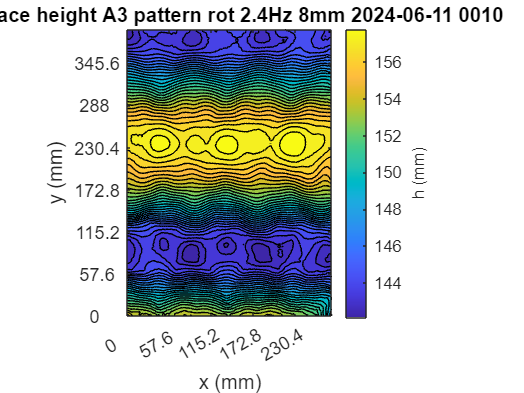

% Plot the surface height & save figure

%surf(h.w)
%showf(h.w)
contourf(h.w, 30);
axis equal
ax = gca;
numbers_long_axis = [0:2.88:394.56];
numbers_short_axis = [0:2.88:282.24];

% Determine the positions of the ticks you want to display (e.g., every 10th label)
x_tick_positions = 1:20:length(numbers_short_axis);
y_tick_positions = 1:20:length(numbers_long_axis);

% Set the ticks at these positions
ax.XTick = x_tick_positions;
ax.YTick = y_tick_positions;

% Set the labels at these positions
ax.XTickLabel = numbers_short_axis(x_tick_positions);
ax.YTickLabel = numbers_long_axis(y_tick_positions);

title('Surface height A3 pattern rot 2.4Hz 8mm 2024-06-11 0010')
col = colorbar;
xlabel('x (mm)');
ylabel('y (mm)');
ylabel(col,'h (mm)');

%caxis([140, 155]);
%w=h.w
%save('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240522_A3_1 Results\20240408_1112_surface_0001.mat','h')
%exportgraphics(gcf,'C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240611_new_A3_results\20240611_rot_2.4Hz_8mm_new_A3_frame_surface_height_0010.png')